# Exploración de distancias

load("occupancy_map_bib.mat")
addpath("dijkstra/")

Mostramos el mapa de ocupación binario con waypoints superpuestos, y sus relaciones de transición. 

show(map)
hold on; 
p = plot(G,'NodeLabel',G.Nodes.Names, 'XData',waypoints(:, 1), 'YData',waypoints(:, 2));
hold off; 

**Prueba de conexidad: **Elegimos 2 puntos de conexión para usar djirstka para encontrar la mejor trayectoria. 

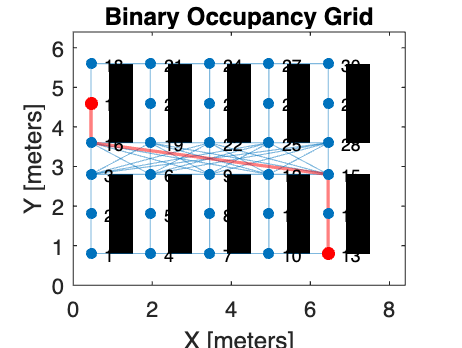

pi = 13; 
pf = 17; 

A = adjacency(G); 
[e, L] = dijkstra(A, pf, pi); 

s = L(1:end - 1); 
t = L(2:end); 

highlight(p,s, t,'EdgeColor','r','LineWidth',1.5); 
highlight(p, [pi, pf], 'NodeColor','red', 'MarkerSize', 5)

## Algoritmo de cálculo de trayectoria

Ser capaz de generar uniones entre stacks de estantes. Se dividrá en 3 partes 

- Trayectoria 1/4 Circular en salida

- Tramo Recto 

- Trayectoria 1/4 Circula de entrada

addpath("utilities/")
N = length(L); 
id_transicion = []; 

for waypoint_id = 1:N-1
    % Id en grafo de cada punto
    pid_i = L(waypoint_id); 
    pid_ii = L(waypoint_id + 1); 

    % (x,y) de cada Punto 
    p_i = waypoints(pid_i, :);
    p_ii = waypoints(pid_ii, :);
    
    % Métricas de comparación @see /utilities
    S = dist(p_i, p_ii);
    phi = angle(p_ii, p_i); 

       
    if abs(phi - 3.1415/2) >= 0.1
        id_transicion = [id_transicion, pid_i, pid_ii]
    end 
end 

id_transicion =     15    16


% Puntos de transición [Futura función]
puntos = waypoints(id_transicion, :)

puntos =     6.4500    2.8000
    0.4500    3.6000


Le = 0.5 * abs(puntos(1, 2) - puntos(2, 2)); 


plot(puntos(:, 1),puntos(:, 2), "--o"); % Distancias

% Circular de salida 
t1 = arc(Le, 100, puntos(1, 1), puntos(1, 2), 0, [-1 0]);

t =     6.4500    2.8000
    6.4499    2.8063
    6.4498    2.8127
    6.4495    2.8190
    6.4492    2.8254
    6.4487    2.8317
    6.4482    2.8380
    6.4475    2.8443
    6.4468    2.8506
    6.4459    2.8569


% Recto
lx = (puntos(2, 1) - puntos(1, 1)) - sign(puntos(2, 1) - puntos(1, 1)) * 2 * Le; 
t2 = [(linspace(0, lx, 100) + t1(end, 1))', ones(size(t1, 1),1 ) * t1(end, 2)];
% Circular de entrada 
punto_final = puntos(end, :); 
punto_incial = t2(end, :); 

ang = rad2deg(angle(punto_final, punto_incial))

ang = 135.0228

t3 = arc(Le, 100, punto_incial(1), punto_incial(2),2, [0, 1]);

t =     0.4503    3.6006
    0.4504    3.5943
    0.4505    3.5880
    0.4507    3.5816
    0.4511    3.5753
    0.4515    3.5690
    0.4521    3.5626
    0.4527    3.5563
    0.4535    3.5500
    0.4543    3.5437


t3 = flip(t3)

t3 =     0.8494    3.2000
    0.8430    3.2001
    0.8367    3.2002
    0.8303    3.2005
    0.8240    3.2009
    0.8177    3.2013
    0.8114    3.2019
    0.8051    3.2026
    0.7988    3.2033
    0.7925    3.2042


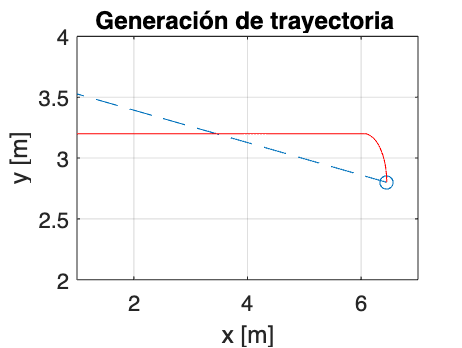

traj = [t1; t2; t3]; 
hold on; 
plot(traj(:, 1), traj(:, 2), 'red'); 
hold off; 
grid on; 
axis([1 7 2 4]); 
xlabel("x [m]"); 
ylabel("y [m]"); 
title("Generación de trayectoria ")

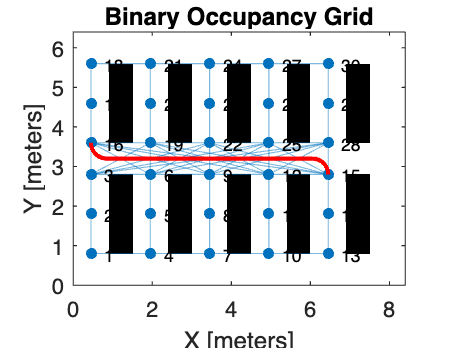

% Unirlo con trayectorias rectas 
show(map)
hold on; 
p = plot(G,'NodeLabel',G.Nodes.Names, 'XData',waypoints(:, 1), 'YData',waypoints(:, 2));
plot(traj(:, 1), traj(:, 2), 'red', 'LineWidth', 2);
hold off; 

## Construcción total

Unimos los segementos funcionales

N = length(L); 
id_transicion = []; 
traj = zeros(1, 2)

traj =      0     0


dy =     0.8000    0.8101    0.8202    0.8303    0.8404    0.8505    0.8606    0.8707    0.8808    0.8909    0.9010    0.9111    0.9212    0.9313    0.9414    0.9515    0.9616    0.9717    0.9818    0.9919    1.0020    1.0121    1.0222    1.0323    1.0424    1.0525    1.0626    1.0727    1.0828    1.0929    1.1030    1.1131    1.1232    1.1333    1.1434    1.1535    1.1636    1.1737    1.1838    1.1939    1.2040    1.2141    1.2242    1.2343    1.2444    1.2545    1.2646    1.2747    1.2848    1.2949


dy =     1.8000    1.8101    1.8202    1.8303    1.8404    1.8505    1.8606    1.8707    1.8808    1.8909    1.9010    1.9111    1.9212    1.9313    1.9414    1.9515    1.9616    1.9717    1.9818    1.9919    2.0020    2.0121    2.0222    2.0323    2.0424    2.0525    2.0626    2.0727    2.0828    2.0929    2.1030    2.1131    2.1232    2.1333    2.1434    2.1535    2.1636    2.1737    2.1838    2.1939    2.2040    2.2141    2.2242    2.2343    2.2444    2.2545    2.2646    2.2747    2.2848    2.2949


t =     6.4500    2.8000
    6.4499    2.8063
    6.4498    2.8127
    6.4495    2.8190
    6.4492    2.8254
    6.4487    2.8317
    6.4482    2.8380
    6.4475    2.8443
    6.4468    2.8506
    6.4459    2.8569


ang = 135.0228

t =     0.4503    3.6006
    0.4504    3.5943
    0.4505    3.5880
    0.4507    3.5816
    0.4511    3.5753
    0.4515    3.5690
    0.4521    3.5626
    0.4527    3.5563
    0.4535    3.5500
    0.4543    3.5437


t3 =     0.8494    3.2000
    0.8430    3.2001
    0.8367    3.2002
    0.8303    3.2005
    0.8240    3.2009
    0.8177    3.2013
    0.8114    3.2019
    0.8051    3.2026
    0.7988    3.2033
    0.7925    3.2042


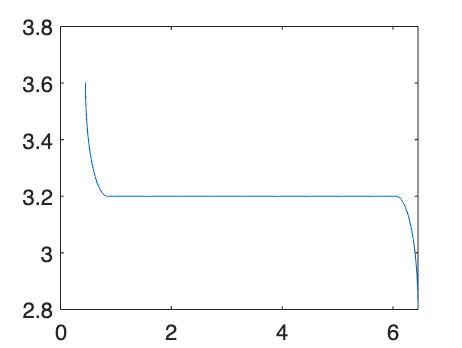

dy =     3.6000    3.6101    3.6202    3.6303    3.6404    3.6505    3.6606    3.6707    3.6808    3.6909    3.7010    3.7111    3.7212    3.7313    3.7414    3.7515    3.7616    3.7717    3.7818    3.7919    3.8020    3.8121    3.8222    3.8323    3.8424    3.8525    3.8626    3.8727    3.8828    3.8929    3.9030    3.9131    3.9232    3.9333    3.9434    3.9535    3.9636    3.9737    3.9838    3.9939    4.0040    4.0141    4.0242    4.0343    4.0444    4.0545    4.0646    4.0747    4.0848    4.0949



for waypoint_id = 1:N-1
    % Id en grafo de cada punto
    pid_i = L(waypoint_id); 
    pid_ii = L(waypoint_id + 1); 

    % (x,y) de cada Punto 
    p_i = waypoints(pid_i, :);
    p_ii = waypoints(pid_ii, :);
    
    % Métricas de comparación @see /utilities
    S = dist(p_i, p_ii);
    phi = angle(p_ii, p_i); 

       
    if abs(phi - 3.1415/2) >= 0.1
        traj = [traj; arc_path([p_i; p_ii])]; 
    else
        dy = linspace(p_i(2), p_ii(2), 100)
        dx = p_i(1) * ones(1, 100);
        traj = [traj; [dx', dy']];
    end 
end 

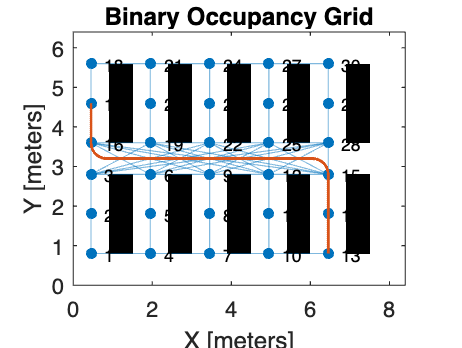


show(map)
hold on; 
p = plot(G,'NodeLabel',G.Nodes.Names, 'XData',waypoints(:, 1), 'YData',waypoints(:, 2));

hold on; 
plot(traj(2:end, 1), traj(2:end, 2), 'LineWidth', 1.4);
hold off; 